Lung

mask_lungs = load('D:\lung-paper\lung_reg\mask\case1_1_5248927\moving\lung.mat');
mask_lungs = double(mask_lungs.image);
mask_lungs(mask_lungs > 0) = 1;
surface_lungs = load('D:\lung-paper\lung_reg\mask\case1_1_5248927\moving\lung_surface.mat');
surface_lungs = double(surface_lungs.image);   
dt_lungs = masked_distance_transform(mask_lungs, surface_lungs);

load("custom_colormap.mat")
mesh(dt_lungs(:,:,80))
colormap (custom_colormap);

Airway

mask_airways = load('D:\lung-paper\lung_reg\mask\case1_1_5248927\moving\airways.mat');
mask_airways = double(mask_airways.image);
mask_airways(mask_airways == 3) = 0;
surface_airways = edge3(mask_airways,'approxcanny',0.5);
dt_airways = masked_distance_transform(mask_airways, surface_airways);

mesh(dt_airways(:,:,50))
colormap (custom_colormap);

Vessel

vessel = load('D:\lung-paper\lung_reg\mask\case1_1_5248927\moving\vesselness.mat');
vessel = double(vessel.image);
vessel(vessel > 0) = 1;

Read Image

img3D = dicomread('D:\lung-paper\lung_reg\dicom\case1_1_5248927\20110224\Recon_2_3');
for img_i = 2 : length(dicomList)
    img2D = dicomread([dicomList(img_i).folder, '\', dicomList(img_i).name]);
    img3D = cat(3, img2D, img3D);
end
img3D = double(img3D);
feature3D = cat(4, dt_lungs, dt_airways,vessel);

save('D:\lung-paper\lung_reg\save_path\feature.mat', "feature3D");
save('D:\lung-paper\lung_reg\save_path\image.mat', "img3D");

clc, clear

patientList = list_folder('D:\lung-paper\NTUH_15-cases\');

for patient_i = 1:length(patientList)

    if any(patientList(patient_i).name == ["case4_2934480(沒有DICOM檔)", "case8_1183453(沒有DICOM檔)"]) % ".", "..", 
        continue
    end

    patientRootPath = [patientList(patient_i).folder, '\', patientList(patient_i).name];
    patientPrePostList = dir(patientRootPath);
    
    for prepost_i = 3 : length(patientPrePostList)
        disp([int2str(patient_i-2), '/', int2str(length(patientList)-2), ':', int2str(prepost_i-2), '/', int2str(length(patientPrePostList)-2)])
%         if any(patientPrePostList(prepost_i).name == [".", ".."])
%             continue
%         end
        dicomFolder = [patientPrePostList(prepost_i).folder, '\', patientPrePostList(prepost_i).name];
        mask_airways = load([dicomFolder, '\airways.mat']);
        mask_airways = double(mask_airways.image);
        mask_airways(mask_airways == 3) = 0;
        surface_airways = edge3(mask_airways,'approxcanny',0.5);
        dt_airways = masked_distance_transform(mask_airways, surface_airways);


               
        mask_lungs = load([dicomFolder, '\lungs.mat']);
        mask_lungs = double(mask_lungs.image);
        mask_lungs(mask_lungs > 0) = 1;
        surface_lungs = load([dicomFolder, '\lungsurface.mat']);
        surface_lungs = double(surface_lungs.image);   
        dt_lungs = masked_distance_transform(mask_lungs, surface_lungs);

        vessel = load([dicomFolder, '\vesselness.mat']);
        vessel = double(vessel.image);
        vessel(vessel > 0) = 1;

        dicomList = dir([dicomFolder, '\*\*.dcm']);
        
        img3D = dicomread([dicomList(1).folder, '\', dicomList(1).name]);
        for img_i = 2 : length(dicomList)
            img2D = dicomread([dicomList(img_i).folder, '\', dicomList(img_i).name]);
            img3D = cat(3, img2D, img3D);
        end
        img3D = double(img3D);
        feature3D = cat(4, dt_lungs, dt_airways,vessel);
        mkdir([dicomFolder, '\preprocessed_output'])
        save([dicomFolder, '\preprocessed_output\feature.mat'], "feature3D");
        save([dicomFolder, '\preprocessed_output\image.mat'], "img3D");      

    
    end
end

7/15:1/4


7/15:2/4


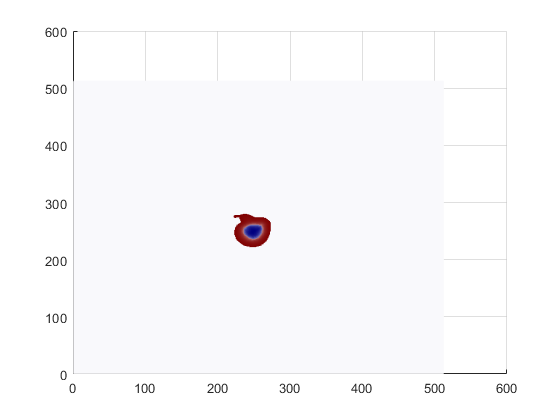

mesh(dt_airways(:,:,50))
load ('D:\lung-paper\custom_colormap.mat')
colormap (custom_colormap);

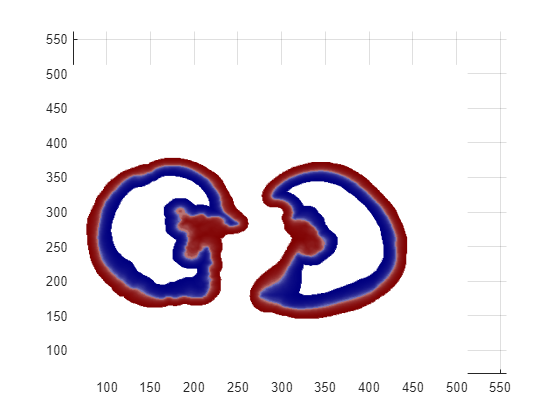

mesh(dt_lungs(:,:,80))
colormap (custom_colormap);

% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%        .mat file to .nii file
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clc,clear

patientList = dir('D:\lung-paper\NTUH_15-cases\*.');

for patient_i = 3 : 3%length(patientList)
    if any(patientList(patient_i).name == ["case4_2934480(沒有DICOM檔)", "case8_1183453(沒有DICOM檔)"]) % ".", "..", 
        continue
    end
    patientRootPath = [patientList(patient_i).folder, '\', patientList(patient_i).name];
    patientPrePostList = dir(patientRootPath);
    
    for prepost_i = 3 : length(patientPrePostList)
        disp([int2str(patient_i-2), '/', int2str(length(patientList)-2), ':', int2str(prepost_i-2), '/', int2str(length(patientPrePostList)-2)])

        dicomFolder = [patientPrePostList(prepost_i).folder, '\', patientPrePostList(prepost_i).name];

        load([dicomFolder, '\preprocessed_output\feature.mat'], "feature3D");
%         load([dicomFolder, '\preprocessed_output\image.mat'], "img3D");      
        
%         V = img3D;
        V = feature3D;
        niftiwrite(V,[dicomFolder, '\preprocessed_output\feature.nii']);


    
    end
end

1/15:1/2
1/15:2/2


% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%        read .nii file
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clear, clc
V_ref = niftiread("D:\lung-paper\NTUH_15-cases\case1_1_5248927\20110224\preprocessed_output\feature.nii");
V_flo = niftiread("D:\lung-paper\NTUH_15-cases\case1_1_5248927\20110526\preprocessed_output\feature.nii");
V_flo_ref_affine = niftiread("D:\lung-paper\NTUH_15-cases\case1_1_5248927\reg\ref_data0_flo_data1_affine_result.nii");
V_flo_ref_nrr = niftiread("D:\lung-paper\NTUH_15-cases\case1_1_5248927\reg\ref_data0_flo_data1_nrr_result.nii");

lung_ref_2D = squeeze(V_ref(:,:,97,1));
lung_flo_2D = squeeze(V_flo(:,:,97,1));
lung_flo_ref_affine_2D = squeeze(V_flo_ref_affine(:,:,97,1));
lung_flo_ref_nrr_2D = squeeze(V_flo_ref_nrr(:,:,97,1));

Overlay Volume

CaseFolder = 'D:\lung-paper\NTUH_15-cases\case1_1_5248927\';
ElementInCaseFolder = dir(CaseFolder);
ref = niftiread([CaseFolder, ElementInCaseFolder(3).name, '\preprocessed_output\image.nii']);
flo = niftiread([CaseFolder, ElementInCaseFolder(4).name, '\preprocessed_output\image.nii']);
registered_flo = niftiread([CaseFolder, 'reg\propagated_image.nii']);

save([CaseFolder, '\case1_1_5248927.mat'], "ref", "flo", "registered_flo")


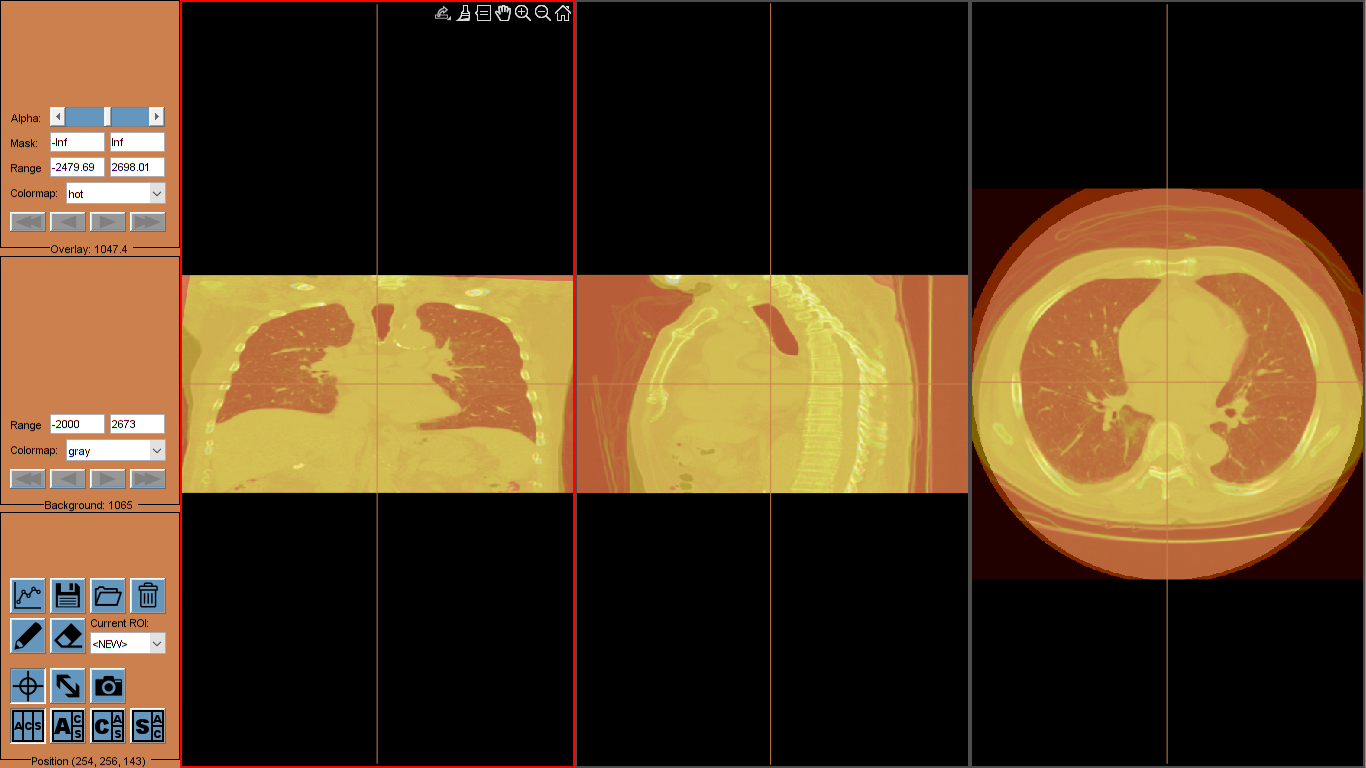

overlayVolume(V1, V2);

Run the script below in command window

clf
for index=150:size(V1, 1)
imshowpair(permute(squeeze(V1(index,:,:)), [2 1]),permute(squeeze(V2(index,:,:)), [2 1]),"montage")
% imshowpair(permute(squeeze(V1(index,:,:)), [2 1]),permute(squeeze(V2(index,:,:)), [2 1]))
pause(1);
end

Find and delete padding

ref_pad_index_1 = [];
for i=1:size(Ref_resized,1)
    if sum(Ref_resized(i,:,:),'all') == 0
        ref_pad_index_1 = [ref_pad_index_1 i];
    end
end
ref_pad_index_2 = [];
for i=1:size(Ref_resized,2)
    if sum(Ref_resized(:,i,:),'all') == 0
        ref_pad_index_2 = [ref_pad_index_2 i];
    end
end
ref_pad_index_3 = [];
for i=1:size(Ref_resized,3)
    if sum(Ref_resized(:,:,i),'all') == 0
        ref_pad_index_3 = [ref_pad_index_3 i];
    end
end

Ref_resized_copy = Ref_resized;
Ref_resized_copy(:,:,ref_pad_index_3) = [];
Ref_resized_copy(:,ref_pad_index_2,:) = [];
Ref_resized_copy(ref_pad_index_1,:,:) = [];

flt_pad_index_1 = [];
for i=1:size(Flt_resized,1)
    if sum(Flt_resized(i,:,:),'all') == 0
        flt_pad_index_1 = [flt_pad_index_1 i];
    end
end
flt_pad_index_2 = [];
for i=1:size(Flt_resized,2)
    if sum(Flt_resized(:,i,:),'all') == 0
        flt_pad_index_2 = [flt_pad_index_2 i];
    end
end
flt_pad_index_3 = [];
for i=1:size(Flt_resized,3)
    if sum(Flt_resized(:,:,i),'all') == 0
        flt_pad_index_3 = [flt_pad_index_3 i];
    end
end

Flt_resized_copy = Flt_resized;
Flt_resized_copy(:,:,flt_pad_index_3) = [];
Flt_resized_copy(:,flt_pad_index_2,:) = [];
Flt_resized_copy(flt_pad_index_1,:,:) = [];

Match image

% Calculate SDD between template and image
I_SSD=template_matching(Ref_resized_copy, Ref.img);
% Find maximum correspondence
[x,y,z]=ind2sub(size(I_SSD),find(I_SSD==max(I_SSD(:))));
[sizex, sizey, sizez] = size(Ref_resized_copy)

sizex = 271

sizey = 338

sizez = 356

disp(1+x-int16(sizex/2));

   39



disp(1+y-int16(sizey/2));

   2



disp(1+z-int16(sizez/2));

   1



isequal(Ref.img(1+x-int16(sizex/2):x-int16(sizex/2)+sizex, 1+y-int16(sizey/2):y-int16(sizey/2)+sizey,1+z-int16(sizez/2):z-int16(sizez/2)+sizez), Ref_resized_copy)

ans = logical
   1


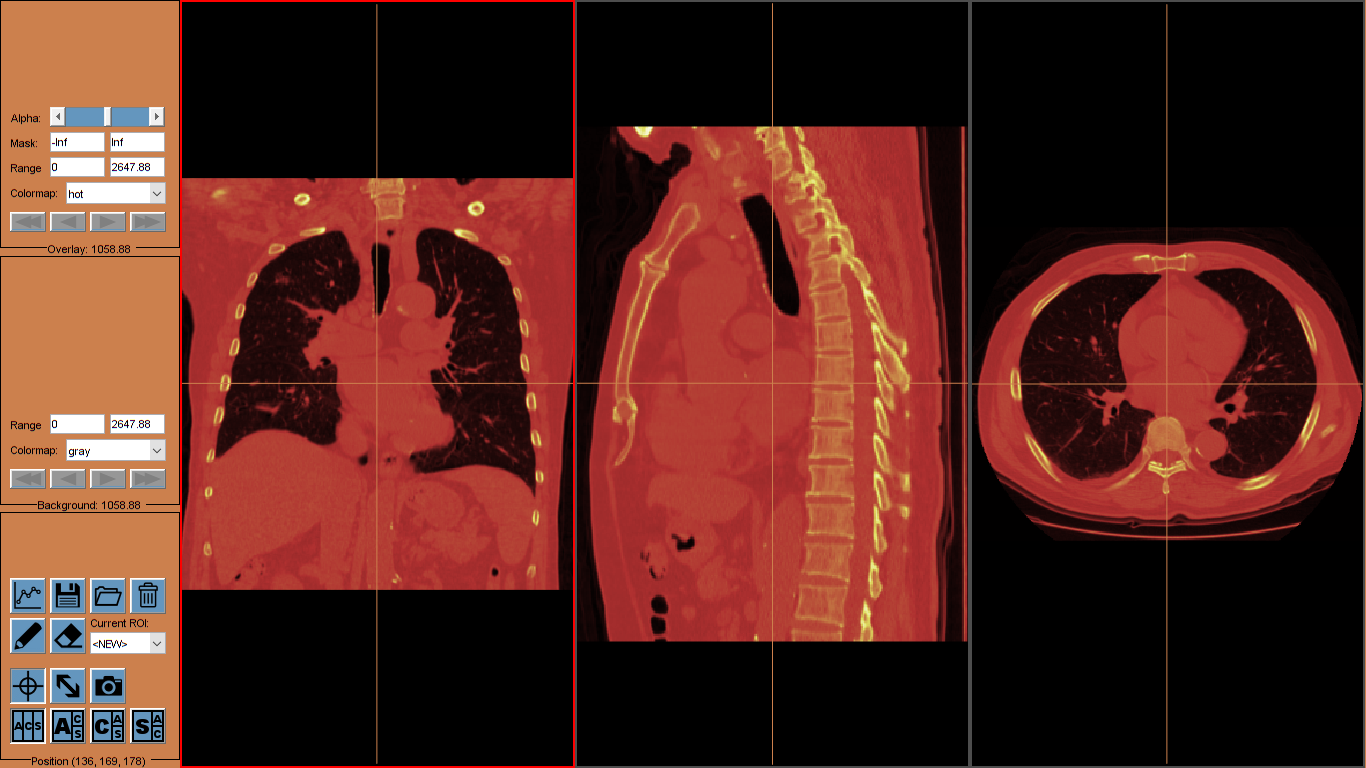

overlayVolume(Ref.img(1+x-int16(sizex/2):x-int16(sizex/2)+sizex, 1+y-int16(sizey/2):y-int16(sizey/2)+sizey,1+z-int16(sizez/2):z-int16(sizez/2)+sizez), Ref_resized_copy)

% Calculate SDD between template and image
I_SSD=template_matching(Flt_resized_copy, Flt.img);
% Find maximum correspondence
[x,y,z]=ind2sub(size(I_SSD),find(I_SSD==max(I_SSD(:))));
[sizex, sizey, sizez] = size(Flt_resized_copy)

sizex = 271

sizey = 340

sizez = 387

disp(1+x-int16(sizex/2));

   49



disp(1+y-int16(sizey/2));

   12



disp(1+z-int16(sizez/2));

   8



isequal(Flt.img(1+x-int16(sizex/2):x-int16(sizex/2)+sizex, 1+y-int16(sizey/2):y-int16(sizey/2)+sizey,1+z-int16(sizez/2):z-int16(sizez/2)+sizez), Flt_resized_copy)

Index in position 2 exceeds array bounds. Index must not exceed 339.

overlayVolume(Flt.img(1+x-int16(sizex/2):x-int16(sizex/2)+sizex, 1+y-int16(sizey/2):y-int16(sizey/2)+sizey,1+z-int16(sizez/2):z-int16(sizez/2)+sizez), Flt_resized_copy)

Control point

ref_cp_matrix = int16(ref_cp_matrix);
flt_cp_matrix = int16(flt_cp_matrix);

cp_ref = zeros(size(Ref.img));
for i=1:size(ref_cp_matrix, 1)
    x = ref_cp_matrix(i,1);
    y = ref_cp_matrix(i,2);
    z = ref_cp_matrix(i,3);
    cp_ref(x,y,z) = i;
end

cp_flt = zeros(size(Flt.img));
for i=1:size(flt_cp_matrix, 1)
    x = flt_cp_matrix(i,1);
    y = flt_cp_matrix(i,2);
    z = flt_cp_matrix(i,3);
    cp_flt(x,y,z) = i;
end

se = strel('sphere',2);
cp_ref_dilate = imdilate(cp_ref,se);
cp_flt_dilate = imdilate(cp_flt,se);
Flt_img = Flt.img;
Ref_img = Ref.img;
niftiwrite(cp_flt_dilate, 'D:\lung-paper\NTUH_15-cases\case1_1_5248927\reg\cp_flt_dilate.nii')

After using Nifty-Reg

propagated_image = niftiread('D:\lung-paper\NTUH_15-cases\case1_1_5248927\reg\propagated_image.nii');
propagated_cp_dilate = niftiread('D:\lung-paper\NTUH_15-cases\case1_1_5248927\reg\propagated_cp_dilate.nii');

Find centor point of dilated control point

centroids = [];
for i=1:20
    tmp_img = propagated_cp_dilate;
    tmp_img(tmp_img ~= i) = 0;
    tmp_img(tmp_img == i) = 1;
    s = regionprops(tmp_img,'centroid');
    centroids = cat(1,centroids,s.Centroid);
end